# Lateral pathways

## Delta_i

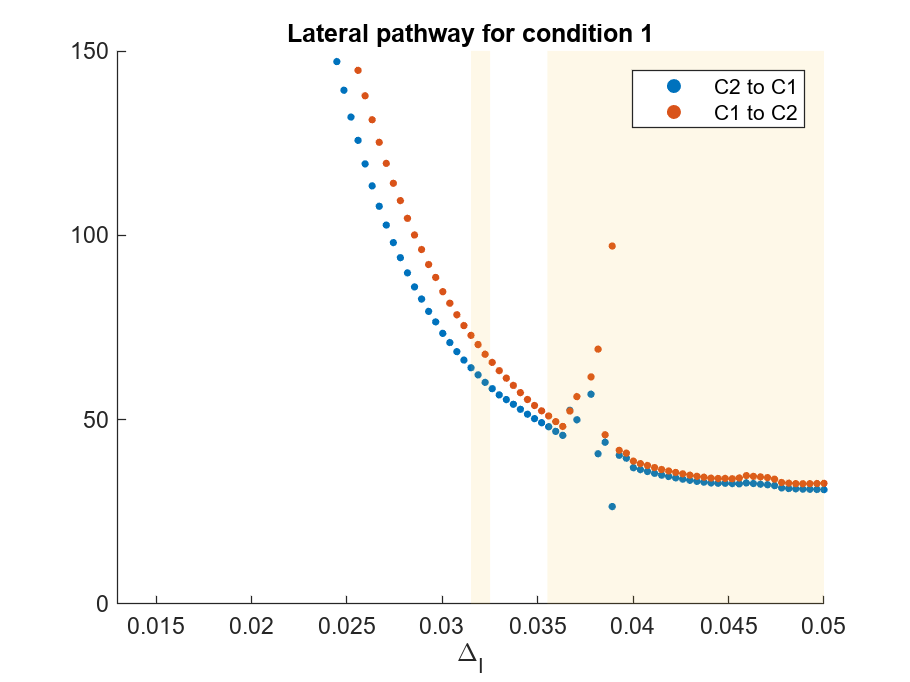

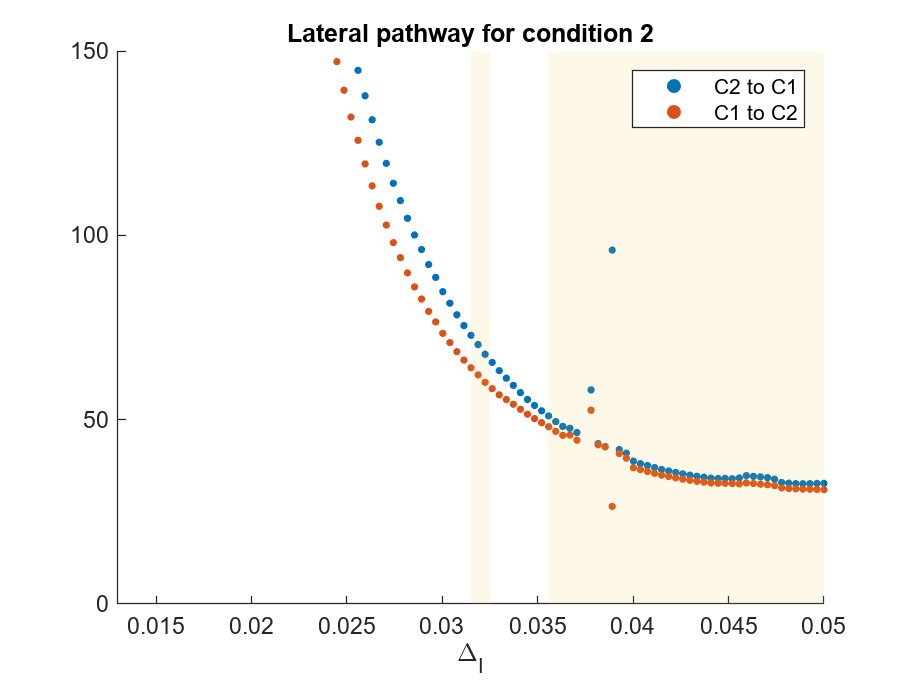

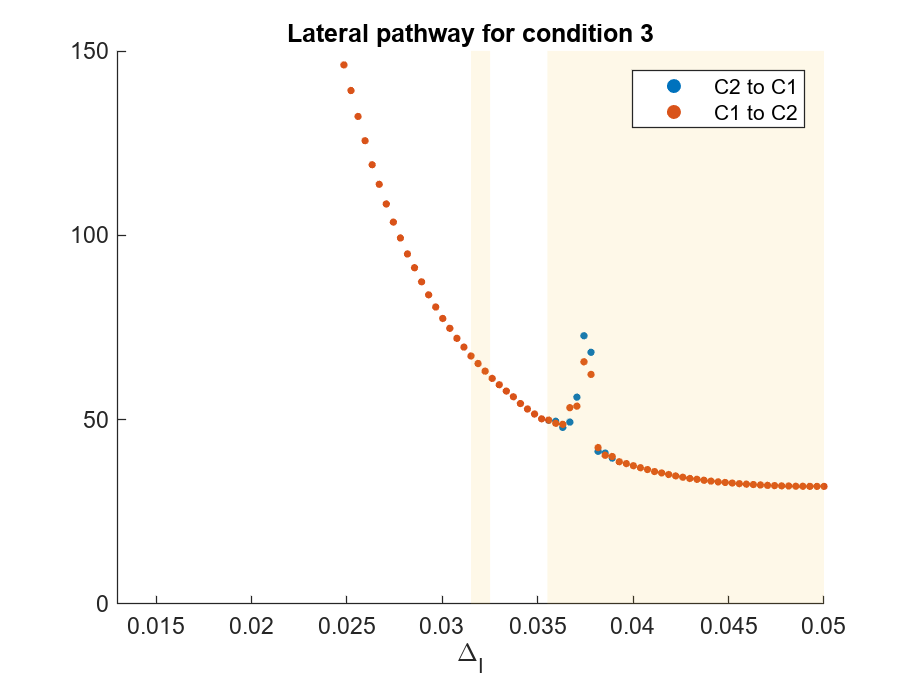

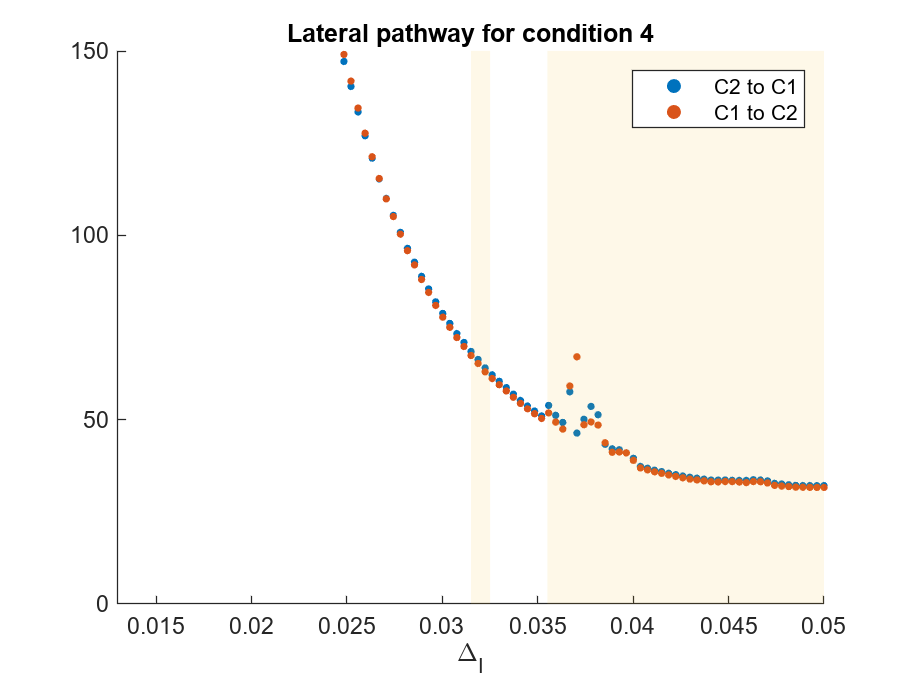

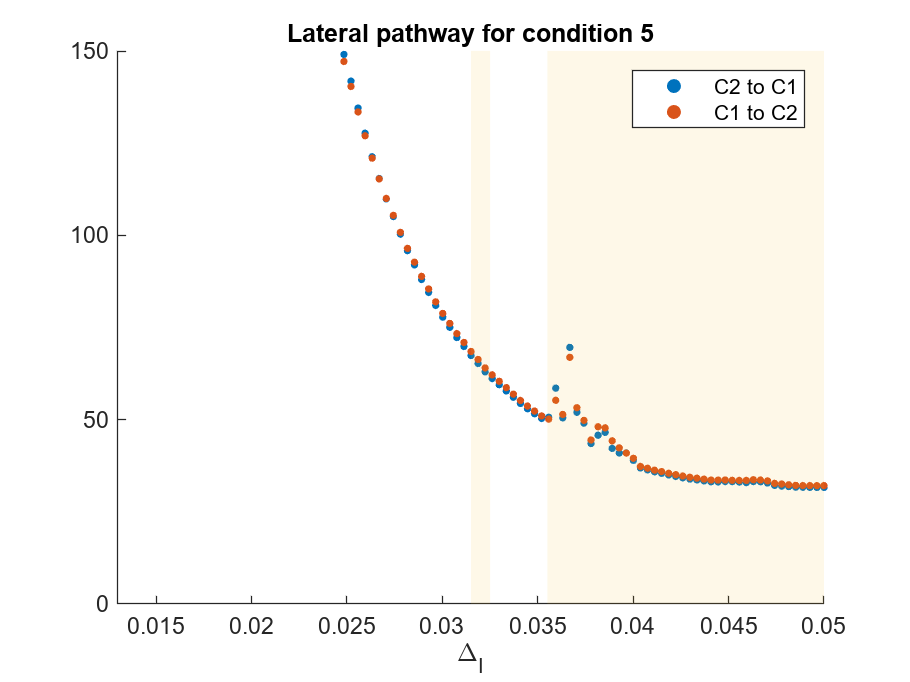

load data/0.28_0.28_0.013_0.05_Iattn_0.02.mat;
startX = 0.013; endX = 0.05;
% lowY = 55; highY = 95;
sz = 10; pop = 5;
x = linspace(startX,endX,size(PET,1));

for i = 1:5
    figure();
    twoOne = PET(:,2,9,i);
    oneTwo = PET(:,10,1,i);

    s1 = scatter(x,twoOne,sz,'filled');
    hold on
    s2 = scatter(x,oneTwo,sz,'filled');

    recX = [0.0355 0.05 0.05 0.0355];
    recY = [0 0 1800 1800];
    r1 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
    alpha(r1,0.1);

    recX = [0.0315 0.0325 0.0325 0.0315];
    recY = [0 0 1800 1800];
    r2 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
    alpha(r2,0.1);
    
    legend([s1 s2],["C2 to C1","C1 to C2"], 'Location','northeast');
    title("Lateral pathway for condition "+i);
    axis([startX endX 0 150]);
    xlabel("\Delta_{I}");
end

## Delta_e

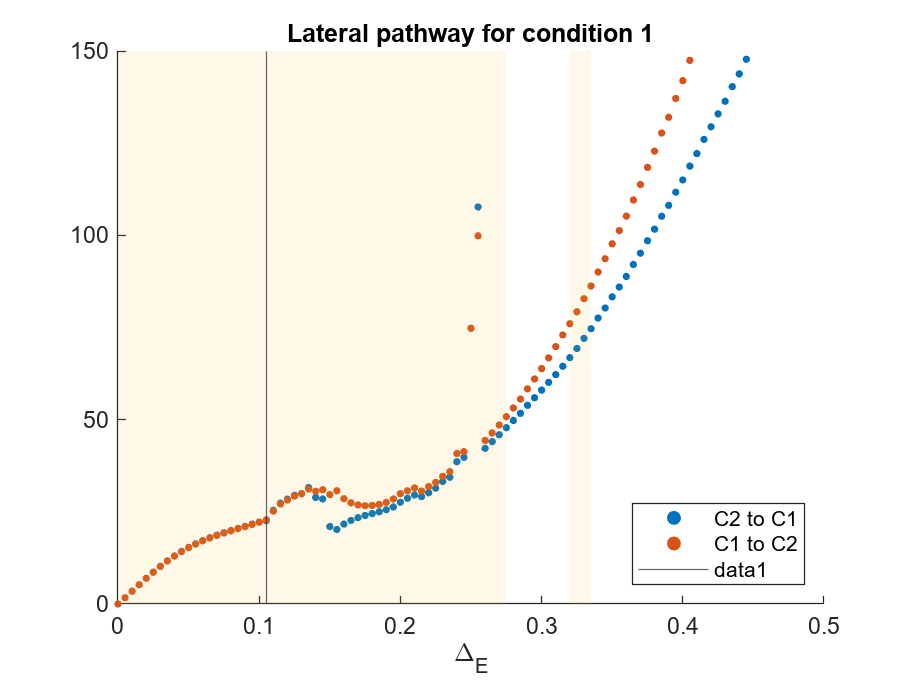

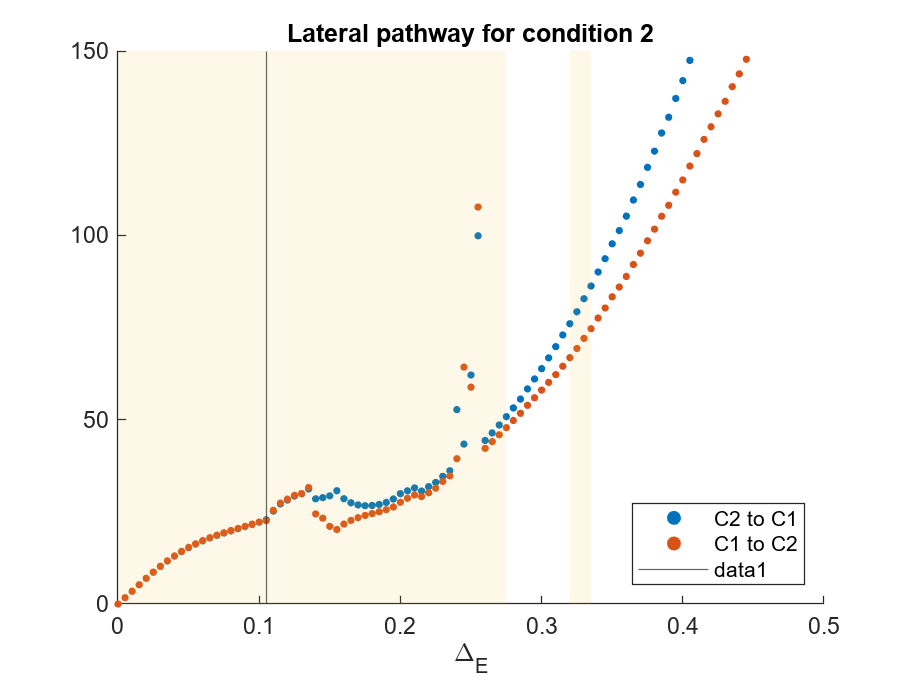

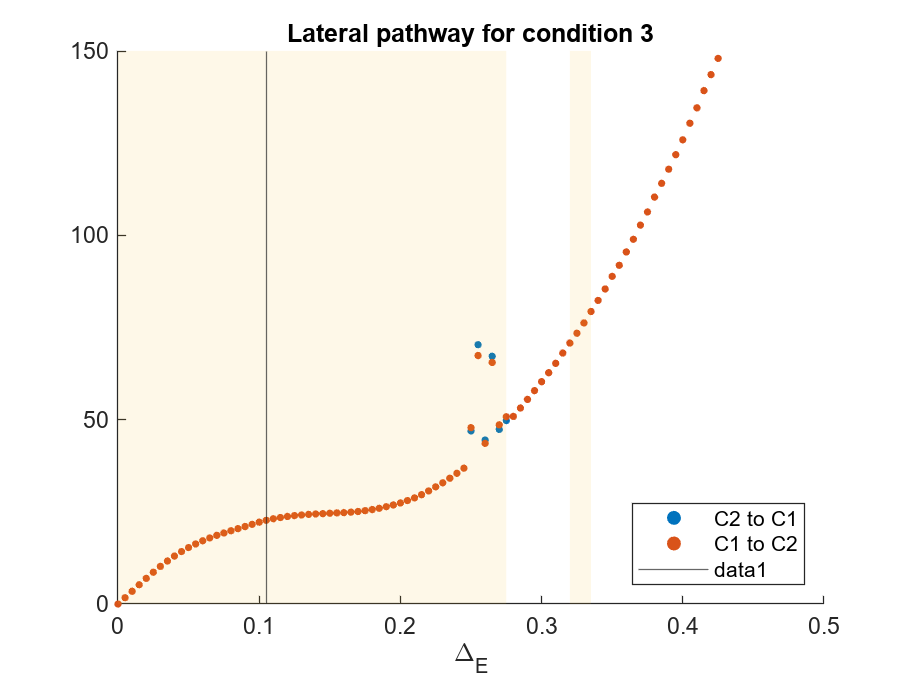

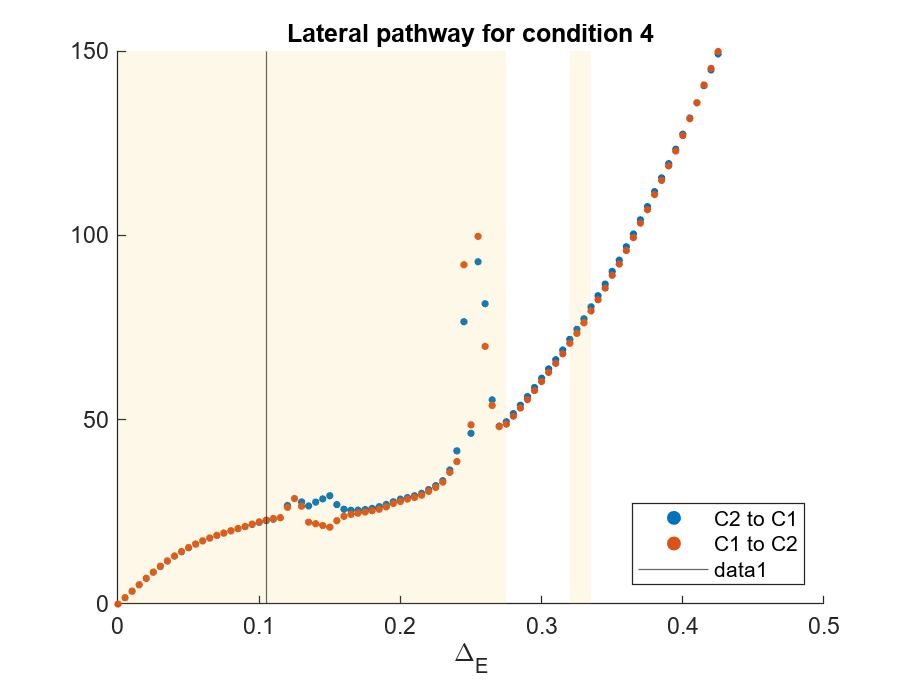

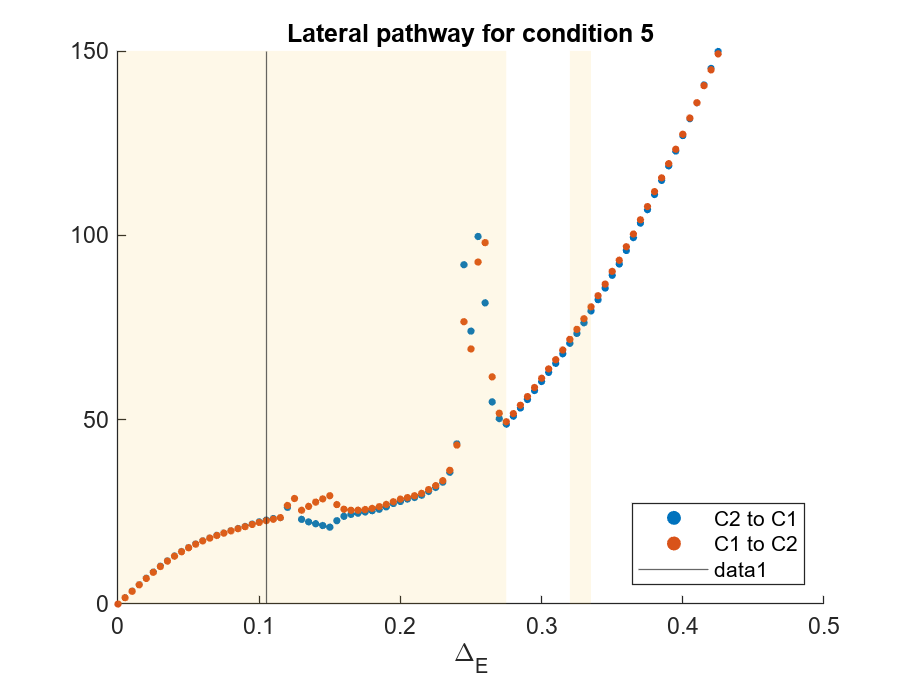

load data/0_0.5_0.035_0.035_Iattn_0.02.mat;
startX = 0; endX = 0.5;
% lowY = 55; highY = 95;
sz = 10; pop = 5;
x = linspace(startX,endX,size(PET,1));

for i = 1:5
    figure();
    twoOne = PET(:,2,9,i);
    oneTwo = PET(:,10,1,i);

    s1 = scatter(x,twoOne,sz,'filled');
    hold on
    s2 = scatter(x,oneTwo,sz,'filled');

    recX = [0 0.275 0.275 0];
    recY = [0 0 300 300];
    r1 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
    alpha(r1,0.1);

    recX = [0.32 0.335 0.335 0.32];
    recY = [0 0 300 300];
    r2 = fill(recX, recY, [245 189 31]/256,'LineStyle','none');
    alpha(r2,0.1);
    
    legend([s1 s2],["C2 to C1","C1 to C2"], 'Location','southeast');
    title("Lateral pathway for condition "+i);
    axis([startX endX 0 150]);
    xlabel("\Delta_{E}");

    xline(0.105);
end